### **Problem 3**

If a digital system has poles exactly on the unit circle, is it considered stable or unstable? Explain. 

***A digital system with multiple poles on the unit circle is considered unstable!***

*In general, Isolated poles on the unit circle may be called marginally stable. The impulse response component corresponding to a single pole on the unit circle never decays, but neither does it grow.*

*But Multiple poles on the unit circle is considered unstable.*

Using MATLAB or Python, provide two examples of system behavior dependent on the input sequence:

a) for a bounded input sequence, the system produces a bounded output sequence:


$$H\left(z\right)=\frac{z^{-1} }{\left(1-0\ldotp 4z^{-1} \right)\left(1-0\ldotp 8z^{-1} \right)}$$


B = [0, 1];            % numerator polynomial
A = [1,-1.2,0.32];   % denominator polynomial
ts = -1;
H1 = tf(B,A,ts,'Variable','z^-1')

H1 =
 
            z^-1
  ------------------------
  1 - 1.2 z^-1 + 0.32 z^-2
 
Sample time: unspecified
Discrete-time transfer function.



pole(H1)

ans =     0.8000
    0.4000


*Poles of H(z) lie inside the unit circle.*

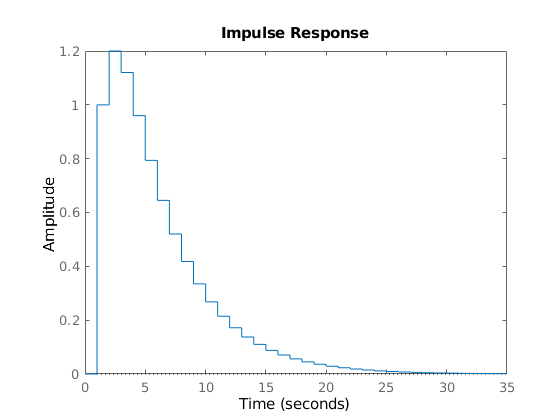

impulse(H1)

*Impulse reponse decays over time!*

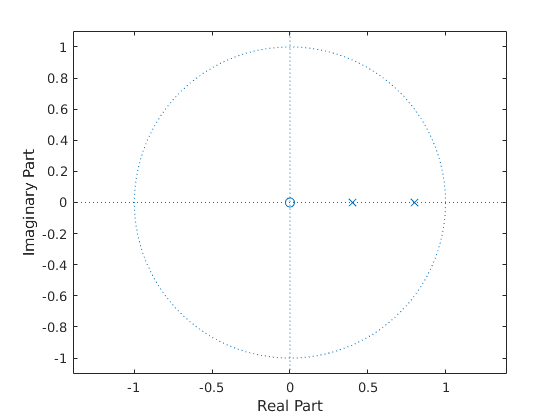

zplane(B,A)

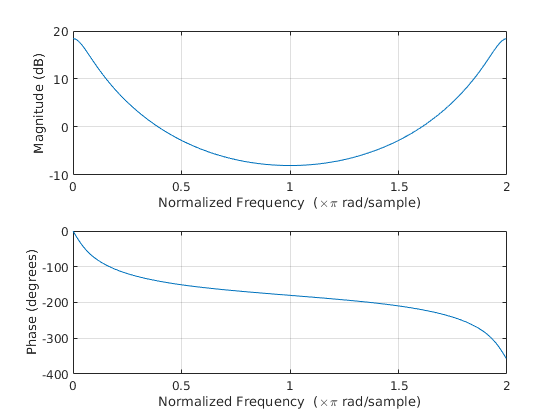

freqz(B,A,'whole')

b) for a bounded input sequence, the system produces an unbounded output sequence


$$H\left(z\right)=\frac{z^{-1} }{\left(1-1\ldotp 5z^{-1} \right)\left(1-0\ldotp 3z^{-1} \right)}$$


B = [0, 1];            % numerator polynomial
A = [1,-1.8,0.45];   % denominator polynomial
ts = -1;
H2 = tf(B,A,ts,'Variable','z^-1')

H2 =
 
            z^-1
  ------------------------
  1 - 1.8 z^-1 + 0.45 z^-2
 
Sample time: unspecified
Discrete-time transfer function.



pole(H2)

ans =     1.5000
    0.3000


*One of the poles lies outside the unit circle!*

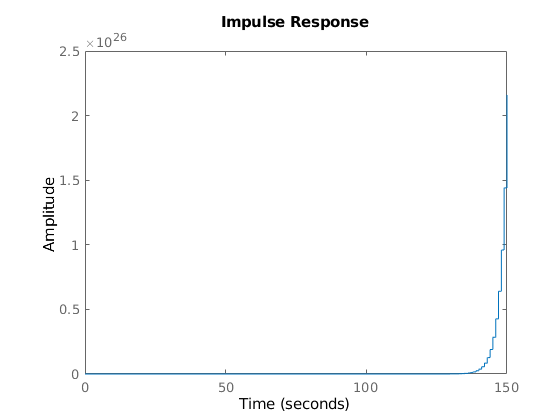

impulse(H2)

*Impulse response grows over time!*

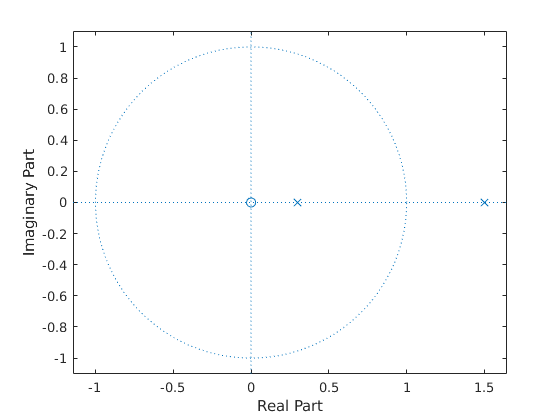

zplane(B,A)

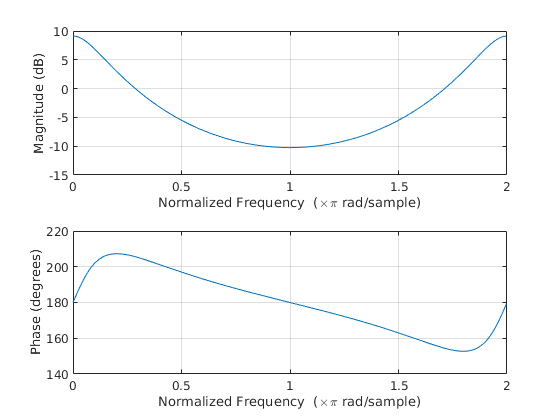

freqz(B,A,'whole')